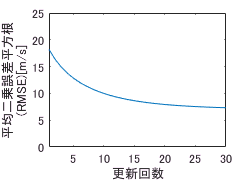

%% 画質評価 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
plot(RMSE(1:30));
xlabel('更新回数')
ylabel({'平均二乗誤差平方根','(RMSE)[m/s]'})
axis tight
ylim([0,25])
exportfig('../result/SART_validation/2018_02_27_new_mse','png',[250,180]);

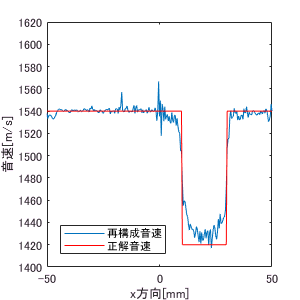

%% プロファイル表示　%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
plot(x_grid*1000,us(t_num/2, :,30))
hold on
plot(x_grid*1000,v_dist(t_num/2,:),'r');
xlabel('x方向[mm]')
ylabel('音速[m/s]')
ylim([1400,1620])
legend('再構成音速','正解音速','Location','southwest')
hold off
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\SART_validation\2018_03_03_new_profile_SART','png',[300,300]);




%% 描画用その1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
subplot(1,2,1);
imagesc(x_grid*1000, y_grid*1000, v_dist);
hold on
scatter(t_pos(1,:)*1000,t_pos(2,:)*1000,3,'r');
hold off
colorbar;
c = colorbar;
c.Label.String = '[m/s]';
set(gca,'YDir','normal');
xlabel('x方向[mm]')
ylabel('y方向[mm]')
caxis([1350 1600])
axis equal;
axis tight
subplot(1,2,2)
imagesc(x_grid*1000,y_grid*1000,us(:,:,13));
colorbar;
c = colorbar;
c.Label.String = '[m/s]';
axis equal;
axis tight;
set(gca,'YDir','normal');
xlabel('x方向[mm]')
ylabel('y方向[mm]')
caxis([1350 1600])
toc
exportfig('../result/SART_aic_window150_1','png',[800,400]);

%% 描画用その2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%いったん収束し，その後発散する様子を示す．
figure
for i = 1:4
subplot(2,2,i);
imagesc(x_grid*1000,y_grid*1000,us(:,:,i));
colorbar;
axis equal;
axis tight;
set(gca,'YDir','normal');
title(['iteration count:',num2str(i),''])
xlabel('x方向[mm]')
ylabel('y方向[mm]')
caxis([1350 1600])
end
exportfig('../result/ART_aic_window120_iter','png',[600,450]);


figure;
histogram(us(:,:,It),'Normalization','probability','BinWidth',5);
hold on
histogram(v_dist,'Normalization','probability','BinWidth',5);


figure;
%%% art_tof_th01.mat%%%
c = categorical({'AIC:window size=50','AIC:window size=100','AIC:window size=120','AIC:window size=150','AIC:window size=200','AIC:window size=300','Threshold method'},'Ordinal',true);
rmse = [min(RMSE_050) min(RMSE_100) min(RMSE_120) min(RMSE_150) min(RMSE_200) min(RMSE_300) min(RMSE_th)];
bar(c,rmse,0.5);
ylabel('Root Mean Squared Error[m/s]');
exportfig('../result/ART_aic_window_comparing','png',[300,400]);